clc;clear;
clc;
clear;
close all;


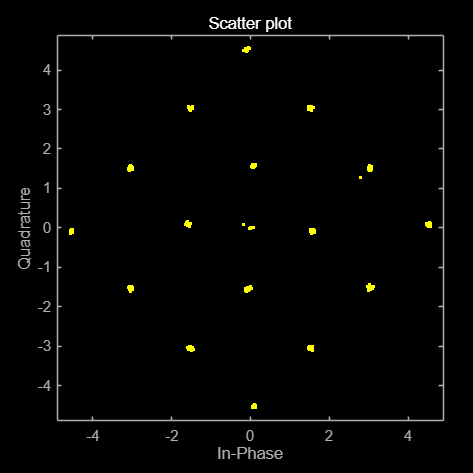

phase_est = -0.7919

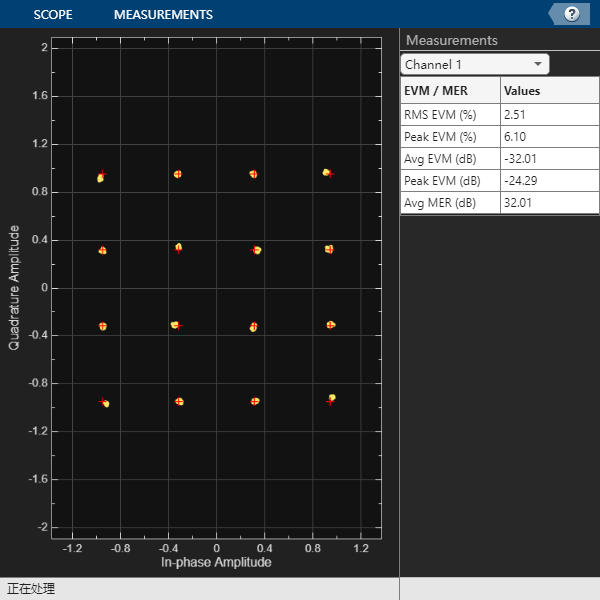

T = tcpclientfind;
if ~isempty(T)
delete(T);
end

port = 11321;          % 与下位机代码保持一致11320端口用来发命令，11321用来收数据


% svr  = tcpserver(ip,port,"ConnectionChangedFcn",@handleConnection);
 h=@saveClient;
 ip="192.168.1.100";
 svr=[];
% svr  = tcpclient(ip,port);
svr  = tcpclient(ip,port);


global gCli gTxQueue          % 永久保存客户端 & 待发队列
gCli = [];                   % 初始为空
gTxQueue = [];               % 待发帧队列

gCli=svr;
%%%
scop=timescope(SampleRate=1e9);
FS=1e9;
global spectrumScope ;
spectrumScope = spectrumAnalyzer("SampleRate",FS, ...
                "ViewType","spectrum", ...
                "SpectrumType","power", ...
                "PlotAsTwoSidedSpectrum",true, ...
                "Method","welch", ...
                "AveragingMethod","exponential", ...
                "SpectrumUnits", "dBm", ...
                "AxesScaling", "Manual", ...
                "YLimits", [-80 +0], ...
                "ForgettingFactor", 0.95, ...
                "FrequencyOffset", 0);
tscop=timescope("SampleRate",1e9);
%%%%%%%%%%%%%%%%主循环%%%%%%%%%%%%%%%%%%%




%回读数据命令  19:命令码   0:工作模式    8：取回的帧数
framenumber=64*1;
readcommand=pack_cmd(19, 0,framenumber);

% out =ZerosTransmit(false);
%  oneframe = pack_cmd(8, 0,1,0,out);  
% 
%           write(svr1, oneframe);  pause(0.5);
%         fre_frame3=pack_cmd(11, 1000e6,3);%第三个参数为1:通道1，2：通道2，3:通道1和2
%           write(svr1, fre_frame3);  pause(0.5);
%         %参考设置**********
%         % referframe=pack_cmd(20,1);   % 0是内参考  1是外参考
%         % write(svr1, referframe);
%         %增益设置**********
%           attenuation=floor((5.3-0)*255/5.3);
%           for i=1:26
%          gainframe=pack_cmd(15, 3,10*(i-1)); 
%   write(svr1, gainframe);  %
%           end
%   % A=read(svr1,length(gainframe));
        write(gCli, readcommand);  %
        data=uint8(read(gCli,(4096*framenumber+16)));  
        flush(gCli);
        for i=1:8
        a=bytes2double(data,tscop);
        end

        % client = svr.Client;
        %  rawSock = getfield(client, 'RawSocket');  % 2020b+ 公开属性
        framelength=typecast(int8(A(17:20)),"int32");

        write(gCli, zeroframe);  %清零
        A=read(svr,24,"int8");

        framelength=typecast(int8(A(17:20)),"int32");
        % start=tic;
        %
        % write(gCli, frame);
        %
        %    toc(start)
        times=0;
        start=tic;
        for i=1:FrameNum
             frame=reshape(waveframe(i,:),[],1);
            write(gCli, frame);

            % %
            A=read(svr,24,"int8");
            % flush(gCli);
            % pause(0.02);
            A2=typecast(int8(A(17:20)),'int32'); %状态0：正常  <0 ：错误
            if A2~=0
                times=i;
                break
            end
            % pause(0.05);
        end
        toc(start)
        write(gCli,extraframe);
        A=read(svr,24,"uint8");







        write(gCli, fre_frame3);
       A2=typecast(int8(A(17:20)),'int32');
        write(gCli, gainframe);
        A=read(svr,24);


        %  pause(1.3);
        %   write(gCli, frame);
        % tcpclientfind
        % write(gCli, fre_frame);
        % a1=typecast(gainframe,"uint8");
        %  write(gCli,gainframe,"uint8");
        % pause(0.1);

        data=uint8(read(gCli,(4096*16+8)*1));
        aa=find(data==17);
        flush(gCli);
        a=bytes2double(data,spectrumScope);
        % b=bytes2double(data,spectrumScope);
        plot(a);
        % csvwrite('qpsk3.csv', a);

        % spectrumScope(a.');
        % duc(a);
        scop(a(1:end).');
        %
        %
        % segmentLength = 100;
        % x=a;
        %
        % [pxx,f] = periodogram(x,hamming(length(x)),length(x),FS,'power');
        % [pwrest,idx] = max(pxx);
        % d=10*log10(pwrest*1000);
        % plot(f,10*log10(pxx*1000));
        % xlabel('rad/sample')
        % ylabel('dB / (rad/sample)')

        %
        % figure (1)
        % plot(a(100:700));
        % fs=1e9;
        % t=0:1/fs:(length(a)-1)/fs;
        %  % a=a.*exp(-j*2*pi*20e6*t);
        % a=a(100:700);
        % Y=2*abs((fft(a)))/length(a);
        % y1=Y(1:length(Y)/2);
        % y2=Y(length(Y)/2:end);
        % Y=[y2 y1];
        % f=-fs/2:fs/length(a):fs/2-fs/length(a);
        % figure (2)
        % plot(f,Y);
        % figure(3)
        % f1=0:fs/length(a):fs/2-fs/length(a);
        % plot(f1,y1);
        % figure(4)
        % f2=-fs/2:fs/length(a):0;
        % plot(f2,y2);
        nn=1;
        % close all;
        % write(gCli, fre_frame);
        % fprintf('已发送：');
        % disp(frame');
        % end
        % end



%% 2. 回调：客户端连上/断开时更新全局变量
function saveClient(src,event)
global gCli
try
if src.Connected
    gCli =src;
    
    % data=read(gCli,8*4096);
    fprintf('客户端 %s:%d 已连接\n', src.ClientAddress, src.ClientPort);

else 
    gCli = [];                  % 清空
    fprintf('客户端已断开\n');
end
catch ME
    fprintf("错误:"+ME.message);
end
end


function cmd_struct = pack_cmd(cmd_type, varargin)
% 创建命令结构体
% cmd_type: 命令类型 (1-18, 100)
% varargin: 根据命令类型传入的参数
    
    % 基础结构体模板
    cmd_struct = struct();
    % 公共头部字段（默认值）
    cmd_struct.head_0 = uint8(0x55);      % 同步头0
    cmd_struct.head_1 = uint8(0xAA);      % 同步头1
    cmd_struct.match_id = uint8(0x01);       % 匹配ID
    cmd_struct.cmd = uint8(cmd_type);     % 命令类型
    cmd_struct.frame_len_reserved =typecast(uint16(0),'uint8') ;     % 帧长度（根据数据填充）
    cmd_struct.cmd_stream_id =typecast(uint16(0),'uint8') ; % 命令流ID
    %4个字节用来传长度
    cmd_struct.frame_len_l =typecast(uint16(0),'uint8') ; % 命令流ID 
    cmd_struct.frame_len_h =typecast(uint16(0),'uint8') ; % 命令流ID
  

    % 根据命令类型处理不同的数据字段
    switch cmd_type
        case 1  % CMD_GET_VERSION
            cmd_struct = setVersionFields(cmd_struct, varargin{:});
        case {2, 3, 4}  % SPI写命令
            cmd_struct = setSpiWriteFields(cmd_struct, cmd_type, varargin{:});
        case {5, 6, 7}  % SPI读命令
            cmd_struct = setSpiReadFields(cmd_struct, cmd_type, varargin{:});
        case 8  % CMD_WRITE_WAVE_BRAM    %波形发送
            cmd_struct = setWaveBramFields(cmd_struct, varargin{:});
            cmd_struct =help(cmd_struct);
        case 9  % CMD_WRITE_AXI_REG
            cmd_struct = setAxiWriteFields(cmd_struct, varargin{:});
        case 10 % CMD_READ_AXI_REG
            cmd_struct = setAxiReadFields(cmd_struct, varargin{:});
        case 11 % CMD_SET_TX_NCO    频率设置
            cmd_struct = setTxNcoFields(cmd_struct, varargin{:});
             cmd_struct =help(cmd_struct);
        case 12 % CMD_SET_RX_NCO
            cmd_struct = setRxNcoFields(cmd_struct, varargin{:});
        case 13 % CMD_LMH6401_WRITE
            cmd_struct = setLmh6401Fields(cmd_struct, 'write', varargin{:});
        case 14 % CMD_LMH6401_READ
            cmd_struct = setLmh6401Fields(cmd_struct, 'read', varargin{:});
        case 15 % CMD_SET_TX_GAIN   设置发射增益
            cmd_struct = setGainFields(cmd_struct,  varargin{:});
            cmd_struct =help(cmd_struct);
        case 16 % CMD_SET_RX_GAIN   设置接收增益
            cmd_struct = setGainFields(cmd_struct,  varargin{:});
             cmd_struct =help(cmd_struct);
        case 17 % CMD_ADC_RETDATA
            cmd_struct = setAdcRetDataFields(cmd_struct, varargin{:});
        case 18 % CMD_SET_DAC_TXEN
            cmd_struct = setDacTxEnFields(cmd_struct, varargin{:});
        case 19 % GET_ADC_STREAM
            cmd_struct = getDacTxEnFields(cmd_struct, varargin{:});
            cmd_struct =help(cmd_struct);           
        case 20 % 参考设置 1是外参考  0是内参考
            cmd_struct = setCMD_SET_LMK04828_REF(cmd_struct, varargin{:});
            cmd_struct =help(cmd_struct);
        case 100 % CMD_RET
            cmd_struct = setRetFields(cmd_struct, varargin{:});
             cmd_struct =help(cmd_struct);
        otherwise
            warning('未知命令类型: %d', cmd_type);
    end
end

%% 辅助函数：设置各命令的特定字段
function cmd = setSpiWriteFields(cmd, cmd_type, spi_addr, spi_data)
    % 设置SPI写命令字段
    cmd.cmd = uint8(cmd_type);
    cmd.spi_addr = uint16(spi_addr);
    cmd.spi_data = uint16(spi_data);
    cmd.frame_len = uint16(4);  % 2字节地址 + 2字节数据
end

%设置频率
function cmd = setTxNcoFields(cmd, frequency, page)
  % tx_freq  = uint32(varargin{1});
  %                   page     = uint8(varargin{2});
  %                   pld(1:4) = typecast(tx_freq,'uint8');
  %                   pld(5)   = page;
    % 设置TX NCO字段
    cmd.tx_fre = typecast(uint32(frequency),'uint8');
    cmd.tx_nco_page = uint8(page);
    % cmd.frame_len = typecast(uint16(5),'uint8');  % 4字节频率 + 1字节页
end

function cmd = setRxNcoFields(cmd, frequency, page)
    % 设置RX NCO字段
    cmd.rx_fre = uint32(frequency);
    cmd.rx_nco_page = uint8(page);
    cmd.frame_len = uint16(5);
end

function cmd = setGainFields(cmd,  channel, gain)
    % 设置增益字段
    % tx_rx: 'tx' 或 'rx'
    % gain: int8类型，范围-128~127 
        cmd.channal = typecast(uint16(channel),'uint8');
        cmd.gain = uint8(gain);
end

function cmd = setDacTxEnFields(cmd, tx_en_page, tx_ch0_en, tx_ch1_en)
    % 设置DAC TX使能字段（包含位字段）
    if nargin == 2
        % 直接传入tx_en_page值
        cmd.tx_en_page = uint8(tx_en_page);
    else
        % 通过位字段设置
        cmd.tx_en_page = uint8(0);
        if tx_ch0_en
            cmd.tx_en_page = bitset(cmd.tx_en_page, 1, 1);  % 位0
        end
        if tx_ch1_en
            cmd.tx_en_page = bitset(cmd.tx_en_page, 2, 1);  % 位1
        end
    end
    cmd.frame_len = uint16(1);
end

function cmd = getDacTxEnFields(cmd,work_mode, adc_stream_frames)
        %% 1. 位域字节：低 3 位 read_src，第 3 位 continuemode，高 4 位 0bitByte = uint8(bitor(bitand(read_src,7), bitshift(continuemode,3)));
        
        %% 1. 位域+保留 4 字节
        hdr = uint32(0);
        hdr = bitor(hdr, bitand(work_mode, 15));  % 低4位放 work_mode
        % 高24位已是0，对应 rsv_0[3]
        union32 = uint32(adc_stream_frames);
        %% 3. 小端打包
        blob = [typecast(hdr, 'uint8').';      % 0-3  header
            typecast(union32,'uint8').']; % 4-7  union
        % 结构体整体对齐到 8 的倍数 → 再补 4 字节
        cmd.blob = [blob; uint8(zeros(4,1,'uint8'))];  % 总 12 字节
end
%******参考设置
function cmd = setCMD_SET_LMK04828_REF(cmd, ref_mode)
    lmkRefBit = ref_mode;            % 0 或 1
    union32   = bitshift(uint32(lmkRefBit),0);   % 只改 bit0
    unionBytes = typecast(union32,'uint8');      % 小端 4 字节
    cmd.ref=unionBytes;
end

%波形数据
function cmd = setWaveBramFields(cmd, base_addr, total_frame, cur_frame, wavedata)
% 设置波形BRAM字段
%输入：base_addr：偏移量
%      total_frame：总帧数量
%      cur_frame:当前帧是第几帧
%      wavedata:波形数据
% 输出：结构体
cmd.base_addr_offset = typecast(uint32(base_addr),'uint8') ;    %偏移
cmd.total_frame = typecast(uint16(total_frame),'uint8');       %总帧数
cmd.cur_frame = typecast(uint16(cur_frame),'uint8');           %当前帧
cmd.wavedata = uint8(wavedata);  
end

function cmd = setRetFields(cmd, rec_cmd, task_frame_data, ret_status)
    % 设置返回命令字段
    cmd.rec_cmd = uint16(rec_cmd);
    cmd.task_frame_data = uint16(task_frame_data);
    cmd.ret_task_status = int32(ret_status);
    cmd.frame_len = uint16(2 + 2 + 4);  % 2+2+4=8字节
end



%*************************
function out =help(input)
%输入input：结构体
%输出out：列向量(结构体成员的值串联起来)
fn = fieldnames(input);
b=[];
for i=1:length(fn)
    temp=fn{i};

    b=[b; reshape(input.(temp),[],1)];
end
if length(b)<32
    out=uint8(zeros(1,32));
out(1:length(b))=b;
else
out=b;
end
end

%%%%%%%%%产生全0信号%%%%%%%
function out =ZerosTransmit(IsZoers)
%% 设置参数

npoint=4096*24;%生成多少数据点
%%%%%%%%%%%%%%%%未启用扫频%%%%%%%%%%%%%%%%%%%%%
if IsZoers==false
AMbase=0.7*ones(1,npoint);
else
 AMbase=0.7*zeros(1,4096*2);
end
% y    =hilbert(AMbase);
a=readmatrix("C:\Users\Administrator\Desktop\共享文件夹\2.csv");

I=a(:,1);
Q=a(:,2);
imax=max(I);
qmax=max(Q);
I=0.7*I/imax;
Q=0.7*Q/qmax;
%*******************
% fs=125e6;
% fc=20e6;
% Rb=1e6;
% sps=fs/Rb;
% 
% M=4;
% 
% 
% symbolnumber=4096;
% databit=randi([0 1],symbolnumber*log2(M),1);
% modsymbol=pskmod(databit,4,pi/4,"gray","InputType","bit");
% 
% %RRC滤波器
% fir=rcosdesign(0.35,12,sps,"sqrt");
% a=conv(fir,modsymbol,"same");
% Txrrc=comm.RaisedCosineTransmitFilter(FilterSpanInSymbols=12,RolloffFactor=0.35,OutputSamplesPerSymbol=sps,...
%   Shape="Square root" );
% a=Txrrc(modsymbol);

fs=125e6;
oversampling=125/2;
filterBeta=0.35;
% fc=5e8;
a=iqmod('sampleRate',fs,'numSymbols',1024,'modType','QPSK','oversampling',oversampling, ...
   'filterType' ,'Square Root Raised Cosine','filterNsym' ,80, ...
   'filterBeta' ,filterBeta,'carrierOffset',0);
I=real(a);
Q=imag(a);
imax=max(I);
qmax=max(Q);
I=0.7*I/imax;
Q=0.7*Q/qmax;
%*******************





% plot(x);
% 量化到 int16（假设满量程 ±1 → ±32767）
% xInt = int16(round(real(y) * 32767));
% yInt = int16(round(imag(y) * 32767));
xInt =int16(round(real(I) * 32767));
yInt =int16(round(real(Q) * 32767));
% 构造 2 通道数据：通道 0 放 x，通道 1 放 x（也可放 0）
ch0_i = xInt(:);   % I 路
ch0_q = yInt(:); % Q 路
ch1_i = xInt(:);   % 同上
ch1_q =  yInt(:);

% 交织成 [ch0_i, ch0_q, ch1_i, ch1_q, ...]
c=int16(zeros(length(xInt),4));
start=tic;
for i=1:length(xInt)
    a=[ch0_i(i),ch0_q(i),ch1_i(i),ch1_q(i)];
    c(i,:)=a;
end
toc(start);
start=tic;
frameInt16 = reshape(c.',[],1);
% frameInt16 = frameInt16(:);         % 拉成一列

% 若想变成字节流（Little-Endian）
out = typecast(frameInt16, 'uint8');   % 长度 *2
end

function data=bytes2double(fileBytes,spectrumScope)
        data_flat = typecast(fileBytes(17:end), 'int16');
        % 重塑为90行8列的矩阵（按行优先顺序）
        data_reconstructed = reshape(data_flat, 8,[])'; % 先reshape为8列90行，再转置
        rec_array=data_reconstructed;
        b=size(rec_array);
        a=zeros(b(1),4);       %通道1数据
        a1=zeros(b(1),4);      %通道2数据
        c=[];
        c1=[];
        channelflag=1;
        for j=1:b(1)
            if channelflag==1
                c= flip(rec_array(j,1:4)) ;  %通道1数据
                c1= zeros(1,4);  %通道2数据
            elseif channelflag==2
                c= zeros(1,4);  %通道1数据
                c1= flip(rec_array(j,5:8)) ;  %通道2数据
            else
                c= flip(rec_array(j,1:4)) ;  %通道1数据
                c1= flip(rec_array(j,5:8)) ;  %通道2数据
            end
            a(j,:)=c;
            a1(j,:)=c1;
        end
        a=a.';
        a=reshape(a,[],1);
        a=double(a)/32767;
        meana=mean(a);
        x=a-meana;
        
        
        a1=a1.';
        a1=reshape(a1,[],1);
        a1=double(a1)/32767;
        meana1=mean(a1);
        x1=a1-meana1;
        % scop=timescope("SampleRate",1e9);
        % scop(x);
        % x=x(200:end-200);
        A=sort(x);
        %计算功率
        minpeak=A(3);
        maxpeak=A(end-3);
        vpp=abs(maxpeak-minpeak);
        pow=10*log10(vpp.^2/(8*50)*1000);
        data=double(a)/32767;
        
        FS=1e9;
        t=(0:length(a)-1)/FS;
        fc=100e6;       
        carrier=exp(-1i*2*pi*fc*t).';
    
       RFreceive=data.*carrier;
       RFreceive=RFreceive./max(abs(RFreceive));
       sps=1e9/6e6;
       if sps==floor(sps)
           spsOut = sps;
       else
           spsOut = floor(sps)+1;
       end
       spsOut = floor(sps)+1;
       [L, P] = rat(spsOut/sps);       % 把 spsOut/nsamp 变成最简分数
       RFreceive  = resample(RFreceive, L, P); 
       % rrc  = rcosderxSigsigRFreceiven(0.35, 12, sps, 'sqrt');
       % rxbaseband = upfirdn(RFreceive, rrc, 1, 1);
%匹配滤波
Rxrrc=comm.RaisedCosineReceiveFilter(DecimationFactor=1,DecimationOffset=0,FilterSpanInSymbols=12,RolloffFactor=0.35, ...
    Shape="Square root",InputSamplesPerSymbol=spsOut);


% 去除高频分量，保留基带信号
% Rs=5e6;rolloff=0.38;
% cutoff_freq = Rs * (1 + rolloff);
% lpf = fir1(100, cutoff_freq/(FS/2));
% RFreceive = filter(lpf, 1, RFreceive);
rxbaseband=Rxrrc(RFreceive);
% 由于sps=200是整数，可以简单找到最佳采样相位
% [L, P] = rat(spsOut/nsamp);       % 把 spsOut/nsamp 变成最简分数
% rxRes  = resample(rxSig, L, P);   % 现在就是 spsOut 采样点/符

%采样定时恢复
sps=spsOut;

signal_sampled =sample_recovery(rxbaseband,sps);
%16QAM
% rx=signal_sampled;
% scatterplot(rx);
% for iter = 1:3
%     % 4.1 去调制（判决引导）
%     M=16;
%     sym_hard = qamdemod(rx, M);
%     sym_hard = qammod(sym_hard, M, 'InputType', 'integer', 'UnitAveragePower', true);
%     z = rx .* conj(sym_hard);
%     % 4.2 平均相位
%     theta_est = angle(mean(z.^4)) / 4;      % 4 次方去 4π 模糊
%     rx = rx .* exp(-1j*theta_est);
% end
% scatterplot(rx);


% rxSignal=signal_sampled;
% scatterplot(rxSignal);
% M=16;
% 
% % 初始化参数
 mu = 0.5;          % 环路步长
% phase_est = 0;      % 相位估计
% phase_history = zeros(length(rxSignal), 1);
% demod_symbols = zeros(length(rxSignal), 1);
% 
% % Costas环处理
% for n = 1:length(rxSignal)
%     % 相位补偿
%     z = rxSignal(n) * exp(-1j*phase_est);
% 
%     % 判决（硬判决）
%     demod_symbols(n) = z;
%     y=z;
%     % 误差检测（适用于QPSK和QAM）
%     if M == 4
%         % QPSK误差检测
%         error = imag(z) * sign(real(z)) - real(z) * sign(imag(z));
%     else
%         % 16QAM误差检测（简化算法）
%           s_hat = qammod(qamdemod(y, M), M, 'UnitAveragePower', true);
%     error = angle(y * conj(s_hat));   % 误差
% 
%         % error = imag(z) * (abs(real(z)) - mean(abs(real(z)))) - ...
%         %         real(z) * (abs(imag(z)) - mean(abs(imag(z))));
%     end
% 
%     % 相位更新
%     phase_est = phase_est + mu * error;
% 
%     % 相位保持在[-pi, pi]范围内
%     phase_est = mod(phase_est + pi, 2*pi) - pi;
% 
%     % 保存相位历史
%     phase_history(n) = phase_est;
% end
% figure
% plot(phase_history);

alpha=0.01;
beta=0.001;
Mu=0.5;
phase_est=carrier_recovery(signal_sampled,"16QAM")



%QPSK
% % 7.1 使用Costas环进行相位跟踪
% % 初始化Costas环参数
% alpha = 0.01;  % 环路滤波器参数
% beta = 0.001;
% phase_est = 0;
% phase_est=carrier_recovery(signal_sampled,alpha,beta);
datademod=pskdemod(rxbaseband,4,pi/4,"bin","OutputType","bit");

  M=16;
 Reference=pskmod(0:3, M,pi/4);
Reference= qammod(0:15, M, 'bin', 'UnitAveragePower', true);
 ConstellationDiagram= comm.ConstellationDiagram(ShowReferenceConstellation=true, ...
                    EnableMeasurements=true,...
                    MeasurementInterval='Current display',...
                    ReferenceConstellation=Reference,...
                    EVMNormalization='Average constellation power');
 rxDecimated=signal_sampled;
 m1=max(abs(Reference));
 m2=max(abs(rxDecimated));

 rxDecimated=m1*rxDecimated/max(abs(rxDecimated));
  factor=m1/m2;
 % rxDecimated=rxDecimated(1200:200:end);\
  % ConstellationDiagram(signal_sampled(60:end));
  xx=0.0;
  % phase_est=mean(phase_history(end-100:end));
         ConstellationDiagram(rxDecimated(9:end).*exp(-1i*(phase_est+xx)));
scatterplot(rxDecimated(51:end).*exp(-1i*phase_est));
        plot(data);
        spectrumScope(data.');
    
end
%**************
